# Projeto 

## META 1

## 1

% Criar tabela
path_g = "data/36"

path_g = "data/36"

path_f = "/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36"

path_f = "/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36"

%files = dir(path_g)
files = dir(path_f)

files = 502×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filteredFiles = files([files.isdir] == 0);
tab = struct2table(filteredFiles)

tab = 500×6 table
         name                                           folder                                               date              bytes    isdir     datenum  
    _______________    ________________________________________________________________________    ________________________    _____    _____    __________

    {'0_36_0.wav' }    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'28-Dez-2020 07:38:02'}    77318    false    7.3815e+05
    {'0_36_1.wav' }    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'28-Dez-2020 07:38:02'}    72478    false    7.3815e+05
    {'0_36_10.wav'}    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'28-Dez-2020 07:38:02'}    87908    false    7.3815e+

% Número de arquivos
nFiles = height(tab);

% Pré-alocar vetores para os dados que serão extraídos
% Lembre que no nome: o primeiro número é o dígito, 
% o segundo é o participante e o terceiro é o número de repetições.
digits = zeros(nFiles, 1);
participants = zeros(nFiles, 1);
repetitions = zeros(nFiles, 1);

% Processar cada nome de ficheiro para extrair os números
for i = 1:nFiles
    % Obter o nome do ficheiro (com extensão)
    filename = tab.name{i};  % Se estiver armazenado como cell array de char
    % Remover a extensão (ex.: '.wav')
    [~, nameNoExt, ~] = fileparts(filename);
    % Separar os componentes usando o underline como delimitador
    parts = split(nameNoExt, '_');
    
    if numel(parts) >= 3
        % Converter os componentes para número
        digits(i) = str2double(parts{1});
        participants(i) = str2double(parts{2});
        repetitions(i) = str2double(parts{3});
    else
        warning('Formato de nome inesperado: %s', filename);
        digits(i) = NaN;
        participants(i) = NaN;
        repetitions(i) = NaN;
    end
end

% Criar a nova tabela com as colunas desejadas:
% - AudioDirectory: diretório de áudio (coluna 'folder')
% - FileName: nome do ficheiro (com extensão, coluna 'name')
% - Participant: segundo número do nome
% - Digit: primeiro número do nome
% - Repetitions: terceiro número do nome
newTable = table(tab.folder, tab.name, participants, digits, repetitions, ...
    'VariableNames', {'AudioDirectory', 'FileName', 'Participant', 'Digit', 'Repetitions'})

newTable = 500×5 table
                                 AudioDirectory                                    FileName        Participant    Digit    Repetitions
    ________________________________________________________________________    _______________    ___________    _____    ___________

    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'0_36_0.wav' }        36           0           0     
    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'0_36_1.wav' }        36           0           1     
    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'0_36_10.wav'}        36           0          10     
    {'/Users/franciscosantos/Desktop/LEI/2º Ano/ATD/MATLAB/Projeto/data/36'}    {'0_36_11.wav'}        36           0          11  

## 2

arquivos = dir(fullfile(path_f, "*.wav"));
nomes = {arquivos.name}';  % Lista de nomes dos arquivos
taxasAmostragem = zeros(length(arquivos), 1);  % Vetor para taxas de amostragem
sinais = cell(length(arquivos), 1);  % Célula para armazenar os sinais

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name); % Caminho completo
    [sinal, fs] = audioread(caminhoArquivo); % Ler áudio
    taxasAmostragem(i) = fs;  % Armazena a taxa de amostragem
    sinais{i} = sinal;  % Armazena o sinal de áudio
end

% Criar tabela com os dados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38637×1 double}
    {'0_36_1.wav' }         48000         {36217×1 double}
    {'0_36_10.wav'}         48000         {43932×1 double}
    {'0_36_11.wav'}         48000         {35604×1 double}
    {'0_36_12.wav'}         48000         {34260×1 double}
    {'0_36_13.wav'}         48000         {35326×1 double}
    {'0_36_14.wav'}         48000         {40242×1 double}
    {'0_36_15.wav'}         48000         {38791×1 double}
    {'0_36_16.wav'}         48000         {41981×1 double}
    {'0_36_17.wav'}         48000         {40212×1 double}
    {'0_36_18.wav'}         48000         {39723×1 double}
    {'0_36_19.wav'}         48000         {39483×1 double}
    {'0_36_2.wav' }         48000         {42

## 3

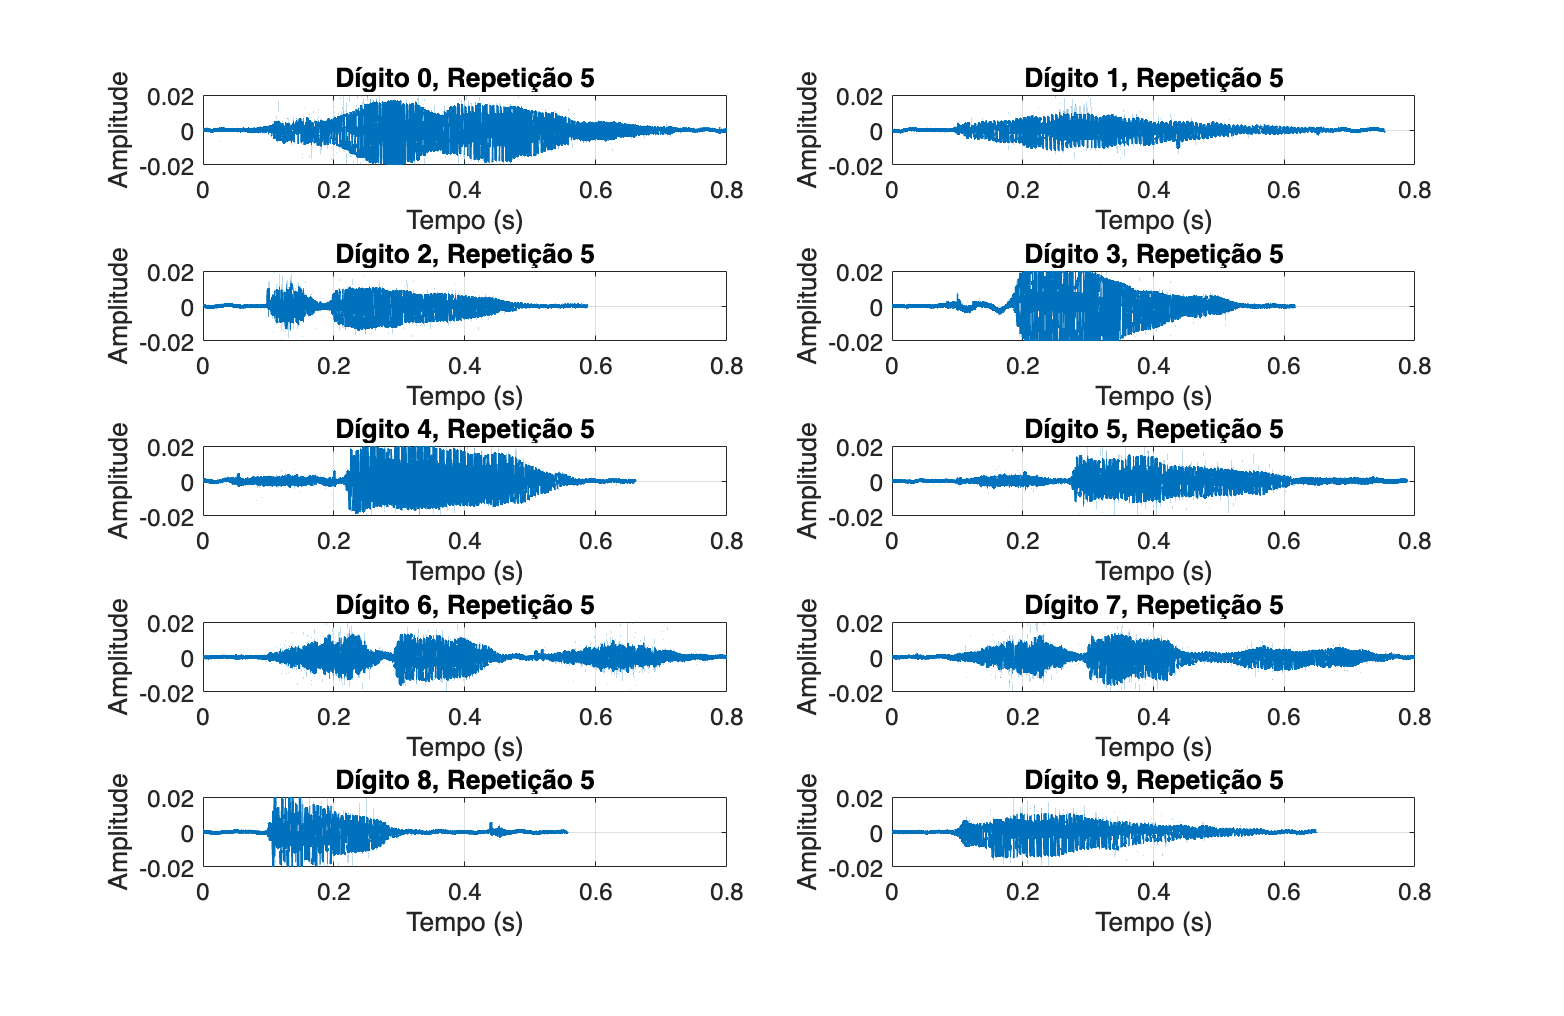

% Extração dos dígitos e repetições (descomente se ainda não executou)
nFiles = height(tabArquivos);
digitos = zeros(nFiles,1);
repeticoes = zeros(nFiles,1);
for i = 1:nFiles
   [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
   partes = split(nomeSemExt, '_');
   digitos(i) = str2double(partes{1});       % Primeiro número = dígito
   repeticoes(i) = str2double(partes{3});      % Terceiro número = repetição
end
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar apenas a repetição 5
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Obter os dígitos disponíveis nessa repetição
uniqueDigitos = unique(T_filtro.Digito);
numDigitos = numel(uniqueDigitos);

if numDigitos < 1
    error('Nenhum dígito disponível na repetição %d.', repEscolhida);
end

% Configuração: dois gráficos por linha
nCols = 2;
nRows = ceil(numDigitos / nCols);

% Criar figura mais alta (80% da altura da tela, por exemplo)
figure('Name', sprintf('Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Loop para plotar cada dígito
for i = 1:numDigitos
    currentDigit = uniqueDigitos(i);
    
    % Seleciona, para o dígito atual, o primeiro arquivo (pode ser adaptado)
    T_current = T_filtro(T_filtro.Digito == currentDigit, :);
    
    sinal = T_current.Sinal{1};
    fs = T_current.Taxa_Amostragem(1);
    
    % Vetor de tempo para o sinal
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot
    subplot(nRows, nCols, i)
    plot(t, sinal, 'LineWidth', 2)  % Aumentando a espessura da linha
    title(sprintf('Dígito %d, Repetição %d', currentDigit, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    set(gca, 'FontSize', 12)  % Aumenta o tamanho da fonte do eixo

    % Ajuste de limites (se desejar deixá-los fixos)
    xlim([0 0.8])
    ylim([-0.02 0.02])
    
    % Se preferir autoajuste no eixo Y, comente a linha acima e use:
    % ylim('auto')
    % ou axis tight (que ajusta todos os eixos):
    % axis tight

    grid on
end